close all
clear 
g = 9.7949;
L = 97.95e-3; % mm
k1 = 60e-3 * g / L; % N/m
k2 = 40.6e-3 * g / L;
k = k1 + k2

k = 10.0599

mk = 28e-3; % kg
m = 214.8e-3;
Na = 224;
la = 122.4e-3 ;
Nb = 236;
lb = 124.6e-3; %mm
beta = 1/3;
omega0_theor= sqrt(k / (m + mk * beta))

omega0_theor = 6.6995

path = "C:/Users/Evgeny/Downloads/rre/"

path = "C:/Users/Evgeny/Downloads/rre/"

A = [];
Phi = [];
Omega = [];
for i=1 : 17
    %if i == 11
    %    continue
    %end
    filename = path + "F (" + int2str(i)+").txt";

    [t, countA, countB] = importfile(filename);
    xa = countA / Na * la;
    xb = countB / Nb * lb;
    xa = xa - mean(xa);
    xb = xb - mean(xb);
    [peaks, locs] = findpeaks(xa);
    T = mean(diff(t(locs)));
    omega = 2 * pi / T;
    [amp, phase] = response(xa, xb);
    A(end+1) =  amp;
    Phi(end+1) = phase;
    Omega(end+1) = omega ;
    sprintf("%.0f omega %f amp %f psi %f", i, omega, amp, phase)
end

ans = "1 omega 5.628833 amp 1.782161 psi 0.996142"

ans = "2 omega 5.055436 amp 1.282254 psi 0.992821"

ans = "3 omega 5.279988 amp 1.419228 psi 0.995536"

ans = "4 omega 6.792633 amp 24.810536 psi 0.078880"

ans = "5 omega 6.851892 amp 24.619330 psi -0.510164"

ans = "6 omega 6.700079 amp 14.301920 psi 0.743708"

ans = "7 omega 6.889458 amp 19.509069 psi -0.731285"

ans = "8 omega 6.684240 amp 12.391776 psi 0.802527"

ans = "9 omega 6.879400 amp 21.710789 psi -0.635345"

ans = "10 omega 6.484939 amp 5.865474 psi 0.991817"

ans = "11 omega 7.400689 amp 3.103520 psi -0.961760"

ans = "12 omega 6.660620 amp 10.337863 psi 0.965152"

ans = "13 omega 7.164407 amp 5.466506 psi -0.943924"

ans = "14 omega 7.012484 amp 8.551720 psi -0.896836"

ans = "15 omega 9.357936 amp 0.665416 psi -0.974762"

ans = "16 omega 9.335018 amp 0.658833 psi -0.974632"

ans = "17 omega 8.312924 amp 1.154797 psi -0.978403"


figure()
%plot(Omega, A, 'x')
[fitresult, gof] = FitAmplitude(Omega, A, k1, k)

expression = '0.596421 /sqrt((1-(om/om0)^2)^2 + (om/om0/Q)^2)'

fitresult =      General model:
     fitresult(om) = 0.596421 /sqrt((1-(om/om0)^2)^2 + (om/om0/Q)^2)
     Coefficients (with 95% confidence bounds):
       Q =       44.24  (42.86, 45.62)
       om0 =       6.824  (6.82, 6.828)

gof = struct with fields:
           sse: 3.7505
       rsquare: 0.9970
           dfe: 15
    adjrsquare: 0.9968
          rmse: 0.5000


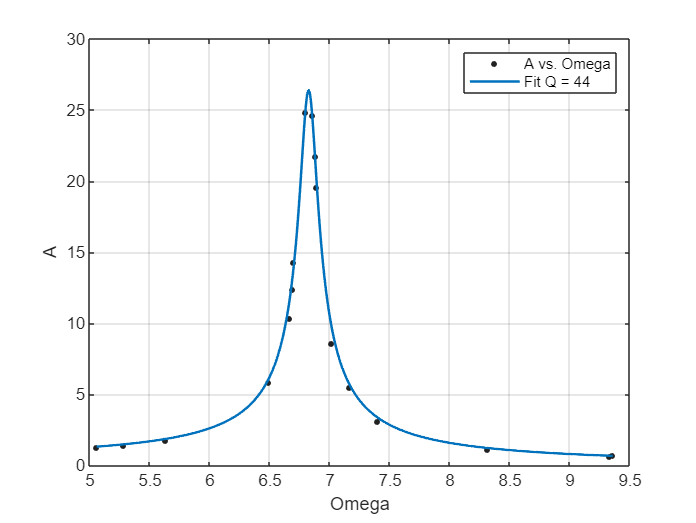

% Plot fit with data.
figure( 'Name', 'Amplitude fit' );
h = plot( fitresult, Omega, A);
legend( h, 'A vs. Omega', sprintf('Fit Q = %.0f', fitresult.Q));
% Label axes
xlabel( 'Omega', 'Interpreter', 'none' );
ylabel( 'A', 'Interpreter', 'none' );
grid on




figure()
%plot(Omega, Phi, 'x')
[fitresult, gof] = FitPhase(Omega, Phi)

fitresult =      General model:
     fitresult(om) = cos( mod( atan(om * om0 / Q / (om0^2 - om^2)), pi))
     Coefficients (with 95% confidence bounds):
       Q =       39.84  (36.03, 43.64)
       om0 =       6.801  (6.796, 6.806)

gof = struct with fields:
           sse: 0.0190
       rsquare: 0.9985
           dfe: 15
    adjrsquare: 0.9984
          rmse: 0.0356


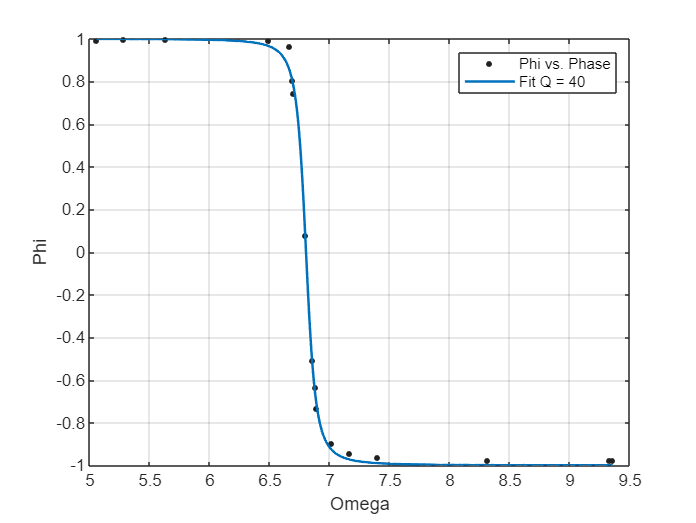

% Plot fit with data.
figure( 'Name', 'Phase fit' );
h = plot( fitresult, Omega, Phi);
legend( h, 'Phi vs. Phase', sprintf('Fit Q = %.0f', fitresult.Q));
% Label axes
xlabel( 'Omega', 'Interpreter', 'none' );
ylabel( 'Phi', 'Interpreter', 'none' );
grid on

function [t, countA, countB] = importfile(filename, dataLines)
%IMPORTFILE Import data from a text file
%  [T, COUNTA, COUNTB] = IMPORTFILE(FILENAME) reads data from text file
%  FILENAME for the default selection.  Returns the data as column
%  vectors.
%
%  [T, COUNTA, COUNTB] = IMPORTFILE(FILE, DATALINES) reads data for the
%  specified row interval(s) of text file FILENAME. Specify DATALINES as
%  a positive scalar integer or a N-by-2 array of positive scalar
%  integers for dis-contiguous row intervals.
%
%  Example:
%  [t, countA, countB] = importfile("D:\resonanse.txt", [2, Inf]);
%
%  See also READTABLE.
%
% Auto-generated by MATLAB on 07-Jan-2025 00:34:01

%% Input handling

% If dataLines is not specified, define defaults
if nargin < 2
    dataLines = [2, Inf];
end

%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts.DataLines = dataLines;
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["Var1", "t", "countA", "countB", "Var5", "Var6"];
opts.SelectedVariableNames = ["t", "countA", "countB"];
opts.VariableTypes = ["string", "double", "double", "double", "string", "string"];

% Specify file level properties
opts.ImportErrorRule = "omitrow";
opts.MissingRule = "omitrow";
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Var1", "Var5", "Var6"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var1", "Var5", "Var6"], "EmptyFieldRule", "auto");

% Import the data
tbl = readtable(filename, opts);

%% Convert to output type
t = tbl.t;
countA = tbl.countA;
countB = tbl.countB;
end

function [amplitude,cosphi] = response(xa, xb)

a = sqrt(dot(xa, xa));
b = sqrt(dot(xb, xb));
ab = dot(xa, xb);
amplitude = b / a;
cosphi = ab / a/ b;
end

function [fitresult, gof] = FitAmplitude(Omega, A, k1, k)
%CREATEFIT(OMEGA,A)
%  Create a fit.
%
%  Data for 'untitled fit 1' fit:
%      X Input : Omega
%      Y Output: A
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 07-Jan-2025 02:21:49


%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( Omega, A );

expression = sprintf('%f /sqrt((1-(om/om0)^2)^2 + (om/om0/Q)^2)', k1/k)
% Set up fittype and options.
ft = fittype( expression, 'independent', 'om', 'dependent', 'A' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [6.8 40];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

end


function [fitresult, gof] = FitPhase(Omega, Phi)


%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( Omega, Phi );

expression = 'cos( mod( atan(om * om0 / Q / (om0^2 - om^2)), pi)) ';
% Set up fittype and options.
ft = fittype( expression, 'independent', 'om', 'dependent', 'A' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [6.8 25];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

end


$A = \frac{k_1}{k_1+k_2} \left[ \left(1-\frac{\omega}{\omega_0}^2\right)^2  + \left(\frac{1}{Q}\frac{\omega}{\omega_0}\right)^2 \right]^{-1/2}, \\

\cos \psi = \cos\, \arctan \frac{1}{Q} \frac{\omega \, \omega_0}{\omega_0^2 - \omega^2}$, 